J_motor = 6.108718942226228e-04;
L_phase = 0.003322599905866;
M_nom = 0.612363655420135;
psi = 0.096178703404314;
R_phase = 0.753894801323517;
U_nom = 48;

Te=L_phase/R_phase;
Tt = 0.2*Te;
Tu=Tt;
Ku = U_nom;
Kp_w = J_motor/2/Tt/psi

Kp_w = 3.6028

Ki_w= 1/(7.9*Tu)

Ki_w = 143.6070

Kp_i = Te*R_phase/(Tt*Ku)

Kp_i = 0.0785

Ki_i = R_phase/(Tt*Ku)

Ki_i = 17.8185

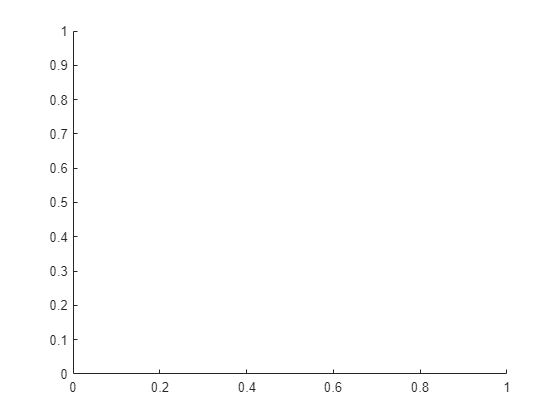



hold on

% plot(out.error.Time, out.error.Data)
plot(out.wmotor.Time, out.wmotor.Data)

Unable to resolve the name 'out.wmotor.Time'.

% plot(out.w_motor_simscape.Time, out.w_motor_simscape.Data)
grid on
xlabel("Time (s)"), ylabel("\omega (rad/s)")
% xlim([1 2])   
hold off
legend("\omega_{motor}")
plot(out.Mmotor.Time, out.Mmotor.Data)
% plot(out.M_motor_simscape.Time, out.M_motor_simscape.Data)
grid on
xlabel("Time (s)"), ylabel("Torque (N·m)")
legend("torque_{motor}")
xlim([0 3])